% Sanaz Hami
% Rewriting Problem 2 Part (a) of Homework 9

% Initialize parameters
a = 1;
b = 1;
T = 0.8;
lambda = 0.2;
errtab = zeros(5,2); % Table to store error and order of accuracy

% Define the initial condition function
f = @(x,y) sin(x+y);

% Start the loop for different grid sizes
for ll = 1:size(errtab,1)
    Nx = 20*2^(ll-1)-1;
    Ny = Nx;
    hx = 2*pi/(Nx+1);
    hy = 2*pi/(Ny+1);
    x = 0: hx : 2*pi - hx;
    y = 0: hy : 2*pi - hy;
    dt = lambda*hx;
    [X,Y] = meshgrid(x,y);
    X = X'; Y = Y';
    v = zeros(Nx+3,Ny+3);
    v(2:Nx+2,2:Ny+2) = f(X,Y);
    v(1,2:Ny+2) = v(Nx+2,2:Ny+2);
    v(Nx+3,2:Ny+2) = v(2,2:Ny+2);
    v(2:Nx+2,1) = v(2:Nx+2,Ny+2);
    v(2:Nx+2,Ny+3) = v(2:Nx+2,2);
    v_new = zeros(size(v));

    for kk = 1:floor(T/dt)
        for ii = 2:Nx+2
            for jj = 2:Ny+2
                v_new(ii,jj) = v(ii,jj) - dt*a*(v(ii,jj)-v(ii-1,jj))/hx-dt*b*(v(ii,jj)-v(ii,jj-1))/hy;
            end
        end
        v = v_new;
        v(1,2:Ny+2) = v(Nx+2,2:Ny+2);
        v(Nx+3,2:Ny+2) = v(2,2:Ny+2);
        v(2:Nx+2,1) = v(2:Nx+2,Ny+2);
        v(2:Nx+2,Ny+3) = v(2:Nx+2,2);
    end
    dt_last = T - floor(T/dt)*dt;
    for ii = 2:Nx+2
        for jj = 2:Ny+2
            v_new(ii,jj) = v(ii,jj) - dt_last*a*(v(ii,jj)-v(ii-1,jj))/hx -dt_last*b*(v(ii,jj)-v(ii,jj-1))/hy;
        end
    end
    v = v_new;
    err = sqrt(hx*hy*sum(sum((f(X-a*T,Y-b*T)-v(2:Nx+2,2:Ny+2)).^2)));
    errtab(ll,1) = err;
end

% Compute the order of accuracy
for kk = 2:size(errtab,1)
    errtab(kk,2) = log(errtab(kk-1,1)/errtab(kk,1))/log(2);
end

% Display the error table
disp('Error Table:');

Error Table:


disp(errtab);

   6.3002e-01            0
   3.2499e-01   9.5502e-01
   1.6455e-01   9.8183e-01
   8.3032e-02   9.8680e-01
   4.1705e-02   9.9346e-01



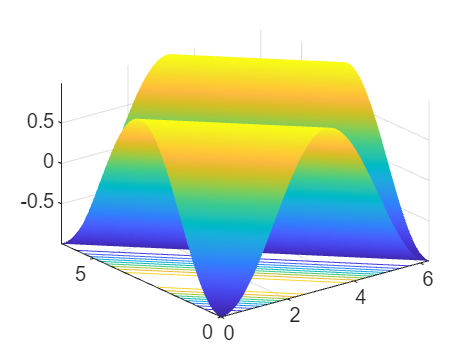

format shortE
% Visualize the solution
surfc(X,Y,v(2:Nx+2,2:Ny+2));
shading interp; % Interpolated shading for smoother visual transition